# Integrated ORP-HEFA Model (All Counties)

This live script is used to run the integrated microalgae model. The modules within the integrated model include:

- **Thermal Model:** Determines pond temperatures and evaporation with hourly resolution in the location of interest

- **Growth Model: **Determines the microalgae growth rate with hourly resolution in the location of interest

- **Cultivation and Dewatering Model:** Determines energy consumption for pumps and paddlewheels, consumption of ammonia, DAP, and CO2, blue and green water footprint, and the net biomass output from cultivation in Open Raceway Ponds (ORPs) with a 3-stage dewatering process (bioflocculation, membrane separation, and centrifugation)

- **Storage Model:** Determines additional requirements for long-term (6+ months) anaerobic biomass storage to offset seasonal production variability, storage losses, and the resulting biomass composition sent to fuel conversion

- **Lipid Extraction Model: **Determines the hexane solvent, electric energy, and thermal energy requirements for high-pressure homogenization (HPH) and the Wet Hexane Extraction (WHE) steps required for lipid extraction and sizes all required equipment.

- **Hydroprocessed Esters and Fatty Acids (HEFA) Model: **Determines the chemicals, catalysts, electric energy, and thermal energy requirements for the HEFA process. The module sizes the refinery equipment required for hydrotreating, isomerization, gas processing, onsite steam-methane reforming (SMR) for hydrogen production and auxiliary equipment including the cooling water tower and pump and a tank farm for short term storage of liquid and gaseous fuels. The HEFA model also determines the hourly output of propane, LNG, naphtha, diesel, and jet fuel. 

- **Anaerobic Digestion Model: **Determines the electric and thermal energy requirements for anaerobic digestion of lipid extracted algae (LEA) for the recovery of nutrients and energy. The digested LEA forms biogas which is cleaned up with the Pressure Swing Absorption (PSA) process and sent to a Combined Heat and Power (CHP) plant. Electric energy is used on-site with excess being sold to the grid. Thermal energy is used on-site with excess considered a zero-value zero-burden waste product. Nutrients recovered in the aqueous supernatant are recycled to algae ponds and solid Nitrogen and Phosphorus in the digestate are land applied to avoid emissions and costs associated with landfilling. 

- **Techno-Economic Analysis (TEA): **Determines the total capital expenditure and annual operational expenses for the integrated biorefinery and solves for the minimum product selling prices (MPSP) for biomass, lipids, jet/diesel fuel, and the contribution to the MPSP from the conversion process only using a 30-year discounted cash flow rate of return (DCFROR) analysis with standard Nth-plant economic assumptions

- **Life Cycle Assessment (LCA):** Determines the life cycle environmental impacts of the integrated biorefinery across all 10 impact categories from the Tool for the Reduction and Assessment of Chemical and other environmental Impacts (TRACI 2.1), and total freshwater consumption 

## Step 1: Define Inputs for the Process Model

While some of the model inputs are adjustable by the user, many inputs are built into the model to increase ease-of-use and ensure accurate reporting. The adjustable inputs are defined by the use below:

clear 
clc
load background_data.mat county_dat

### 1.1 Facility Size and Layout:

Select the facility size in total wetted-acres and specify the size of individual ponds. Expect the MBSP and MFSP to increase significantly with facility sizes smaller than 5000 wetted-acres due to economies of scale.

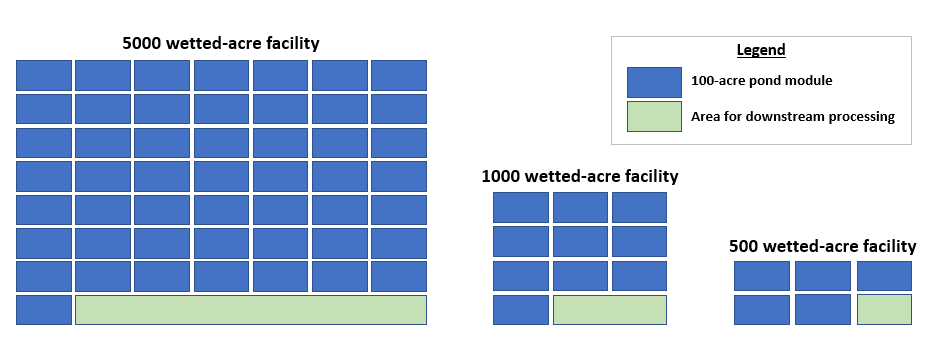

wetted_acres = 5000; % wetted-acres
pond_size = 10; % acres
depth = 0.2; % m
max_depth = 0.25*100; % enter in m, converted to cm
min_depth = 0.15*100; % enter in m, converted to cm
Rainfall = "Off";

*"Max Pond Depth" must be greater than "Pond Depth" and "Min Pond Depth" must be less than "Pond Depth" specified above.*

% Facility Size and Layout 
num_ponds = ceil(wetted_acres/pond_size);
module_size = 100; % wetted-acres (fixed)
    if pond_size == 10
        if wetted_acres == 5000
            length_orp = 2*670*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 2*670*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    else 
        if wetted_acres == 5000
            length_orp = 4*417*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 4*417*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    end 

% Define Geometry Vector as Model Input 
geom_vec = [length_orp width depth max_depth min_depth] ;

### 1.2 Harvesting Sequence:

Define harvesting parameters for the cultivation facility including the pond inoculation concentration, the concentration at which harvesting is triggered, and maximum days between automated harvesting events (regardless of pond concentration). If "Rainfall" is turned on, harvesting is also triggered when rainfall causes the pond depth to exceed the maximum allowable depth specified above. *Please note the harvesting concentration must be greater than the inoculation concentration.*

% Harvest sequence, concentrations in gpL and days to harvest
CX_inoculation = 0.1*1000; % entered as gpL and converted to g/m3
CX_harvesting = 0.6*1000; % entered as gpL and converted to g/m3
harv_days = 5; % days until automated harvest cycle is triggered

%Build model input vectors
harvest_vec = [CX_inoculation CX_harvesting harv_days 250 4000]; %[initial_CX final_CX days_to_harvest i_salt salt_max_cx]

strain = "S_obliquus"; 
strain_vec =[305.4, 276.2, 314.1, 0.38, 480, 0.03, 1.5]; %[max temp, min temp, optimal temp, ODC, sat light intensity, dark respiration losses, phi] - phi is photon efficiency of 12 g biomass/8 mol photons = 1.5

### 1.3 Nutrients and CO2 Consumption Parameters:

Define the C, N, and P content of the microalgae to quantify the consumption of ammonia, DAP, and CO2 used for cultivation. *Please enter percentages in decimal form (for example, 25% is entered as 0.25).*

**    Carbon Content and Carbon Utilization Efficiency:**

c_content = 0.574; % ash-free dry weight basis 
sparge_eff =  0.9; %Carbon utilization efficiency (CUE)

%Optional inputs to include CO2 capture energy and emissions in boundary
CO2_capture_elec_en = 0; %MJ elec/tCO2 captured supplied by local grid
CO2_capture_therm_en = 0;  %MJ thermal/tCO2 captured supplied by NG - enter 0 and include emissions from thermal energy gen. in indirect emissions when using waste heat 
CO2_capture_indir_GHG = 0;  %GHG from CO2 capture consumables (MEA, water, other chemicals, sorbents, solvents, etc.) - will vary based on CO2 capture tech.

%Build model input vectors
co2_capt_lci = [CO2_capture_indir_GHG; CO2_capture_therm_en; CO2_capture_elec_en];

**    N + P Content in Algae and Nutrients:**

rep_dep = "Nutrient Replete";
p_content = 0.002; % ash-free dry weight basis
n_content = 0.016; % ash-free dry weight basis
p_content_dap = 0.2; % dw basis
n_content_dap = 0.18; % dw basis
n_content_ammonia = 0.82; % dw basis

    switch rep_dep
        case 'Nutrient Replete'
        nutrient_surpluss = 0.2; % percentage surplus of nutrients supplied
        case 'Nutrient Deplete'
        nutrient_surpluss = 0.0; % percentage surplus of nutrients supplied 
    end 

**    Transportation distances for Ammonia:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
ammonia_transp_lorry = 148;
ammonia_transp_train = 276;
ammonia_transp_inland_ww = 47;
ammonia_transp_sea_container = 841;

**    Transportation Distances for DAP:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
DAP_transp_lorry = 148;
DAP_transp_train = 276;
DAP_transp_inland_ww = 47;
DAP_transp_sea_container = 841;

%Build model input vectors
transp_vec = [ammonia_transp_train, ammonia_transp_inland_ww, ammonia_transp_lorry, ammonia_transp_sea_container; % ammonia
              DAP_transp_train, DAP_transp_inland_ww, DAP_transp_lorry, DAP_transp_sea_container]; % DAP

### 1.4 Inputs for Anaerobic Storage:

    **Microalgae Composition (dry weight basis):**

*    Please note the algae composition must sum to 100% (proteins + carbohydrates + lipids + ash = 100%). Enter percentages in decimal form. *

prot = 0.09; % dry wt%
carb = 0.421; % dry wt%
lip = 0.412; % dry wt%
ash = 0.077; % dry wt%

sum_comp = (prot + carb + lip + ash)*100;
fprintf('Current Sum = %0.2f %%', sum_comp);

Current Sum = 100.00 %

**    Anaerobic Storage Parameters:**

degradation = 0.05; % dry matter lost to acid formation - based on Wendt et al., 2019 (INL)
centr_out_dens = 1042; %kg/m3 - Li et al., 2020
pump_eff = 0.7; % pumping efficiency

% Build model input vector - comp_vector
comp_vector = [c_content sparge_eff p_content p_content_dap n_content_dap n_content n_content_ammonia nutrient_surpluss ash];

### 1.5 Inputs for Lipid Extraction Model:

    **Lipid Extraction System Boundary and Operational Days:**

LE_inc_AD_CHP = "Yes";
annual_uptime = 330; 

%Calculate annual operational hours based on operational days
op_hours = annual_uptime*24;

    **High-Pressure Homogenization:**

HPH_num_passes = 1; % Tetraselmis = 1 (low pressure); Chlorella = 2 (high pressure); Nanno = 6 (high pressure) 
HPH_pressure = 400;   % high pressure = 1500 bar; low pressure = 400 bar
    if HPH_pressure == 1500
    HPH_flowrate = 5; % m3/hr per unit
    else 
    HPH_flowrate = 23; % m3hr per unit 
    end 

    **Wet Hexane Extraction (WHE):**

WHE_thermal_en = 1.7; % 1.7 kWh_thermal/kg oil
WHE_electric_en = 0.54; % 0.54 kWh_elec/kg oil
WHE_solvent_to_biomass = 1.8; % 1.8 g hexane/g wet biomass
WHE_hexane_loss = 5.2; % 5.2 g hexane/kg oil
WHE_extraction_eff = 99/100; % 95 percent of lipids extracted

%Build model input vector
WHE_model_inputs = [WHE_thermal_en; WHE_electric_en; WHE_solvent_to_biomass; WHE_hexane_loss; WHE_extraction_eff];

### 1.6 Inputs for Hydroprocessed Esters and Fatty Acids (HEFA) Model:

    **HEFA Process Options (Fuel Profile and H2 Production):**

HEFA_scenario = "Maximum Jet"; % Maximum Jet or Maximum Distillate
HEFA_H2_scenario = "Purchased"; % Purchsed or Onsite SMR
HEFA_CO2_recycle = "No"; % Recycle CO2 to pond? Yes//No
ng_boiler_eff = 0.8; % Natural gas boiler efficiency (80% default)

### 1.7 Inputs for the Techno-Economic Analysis

Use this section to define commodity prices such as ammonia, DAP, electricity, and CO2 and to define critical assumptions for the cash flow analysis.

    **Assumptions for the Discounted Cash Flow Rate of Return Model:**

Cost_year = 2019; % cost year used to adjust CAPEX and OPEX
IRR = 0.1; % Internal Rate of Return in DCFROR 

    **Commodity Prices and Transportation Distances:**

*    Default commodity prices are reported in 2019 dollars. Enter commodity prices in 2019 dollars and all costs are indexed within the model to the "Cost Year" entered above.*

    Cultivation Consumables:

load background_data.mat

% Cost Indices and establishing project year
CAPEX_INDEX = table2array(CAPEX_CEPI_INDEX);
CHEM_INDEX = table2array(CHEMICAL_INDEX); 
ELEC_INDEX = table2array(ELEC_INDEX);
LABOR_INDEX = table2array(LABOR_INDEX);

CAP_IND_POS = Cost_year - 1989; 
CHEM_IND_POS = Cost_year - 1979; 
ELEC_IND_POS = Cost_year - 2013; 
LABOR_IND_POS = Cost_year - 1989; 

%Commodity prices
Elec_cost = 0.07*(ELEC_INDEX(ELEC_IND_POS,2)/ELEC_INDEX(6,2)); % 2019$/kWh - EIA (2019)
CO2_cost =50; % $/tCO2
ammonia_cost = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
dap_cost = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)

    Lipid Extraction and HEFA Consumables:

%Commodity prices - all prices indexed to project year using 
NG_cost = 0.2154*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % 2011$/kg - $5.10/1000 scf - Dutta et al., 2011; indexed to 2019 dollars
H_cost = 1.47*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % 2012$/kg - Dilich et al., 2012; indexed to 2019 dollars
Process_water_cost = 0.204/1000*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % $/m3 converted to $/kg - 2011$/kg - Dutta et al., 2011; indexed to 2019 dollars
Hexane_cost = 0.71*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(36,2)); % $/kg - assumption based on 2015 market price ($670-710/MT N Hexane) indexed to proj year
carbon_offset_cost = 45; % $45/tCO2 -assumption 
lip_purch_price = 0.75; % $0.75 per kg lipid for conversion only system boundary

% Critical Inputs Cost Matrix
cost_matrix = [Elec_cost, ammonia_cost, dap_cost, CO2_cost]; %$/kWh, $/kg ammonia, $/kg DAP, $/tCO2
SAF_consumables_costs = [Elec_cost; ammonia_cost; dap_cost; CO2_cost; NG_cost; 0; H_cost; Process_water_cost; Hexane_cost; carbon_offset_cost; lip_purch_price];

*    *For the "Conversion Only" system boundary please enter an oil/lipid (feedstock) purchasing price.*

    Fuel Product Values*:*

% Value of produced fuel products - https://afdc.energy.gov/fuels/prices.html
value_propane_gal = 3.55; 
value_LNG_gal = 3.63; % $/DGE (6.059 lbs of LNG per DGE)
value_naphtha_gal = 4.05; 
value_jet_gal = 2.46; 
value_diesel_gal = 5.17;
SAF_fuels_value_mat = [value_propane_gal; value_LNG_gal; value_naphtha_gal; value_jet_gal; value_diesel_gal];

    **DGE = Diesel Gallon Equivalents (6.059 lbs of LNG per DGE*

    *Fixed Operational Expenses Costing Model:*

fixed_opex_case = "Pearlson"; % Pearlson or Chen and Quinn

% SAF model dropdown menu inputs for model
SAF_dropdowns = [LE_inc_AD_CHP; HEFA_scenario; HEFA_H2_scenario; HEFA_CO2_recycle; fixed_opex_case];

## Step 2: Run the Model with the Current Inputs

 
% Find list of weather data files
Location = 'Merger';
D = dir([Location,'\*.csv']);
filenames = {D(:).name}.';

% Pre-allocate variables for the for loop 
heat_map_data = zeros(length(filenames), 57); 

for i = 1:length(filenames)
    file_id = erase(filenames{i},'.csv');
    file = "Merger/" + file_id + ".csv";
    file_code = readtable(file,'Range','B1:B1','ReadVariableNames',false); 
    weather = readtable(file,'Range','G3:K8762','ReadVariableNames',false); 
    coord =  readtable(file,'Range','F1:G1','ReadVariableNames',false); 
    
    id_county = county_dat((find(county_dat(:,1) == file_id)),3);  
    id_state = county_dat((find(county_dat(:,1) == file_id)),4); 
    id_FIPS = county_dat((find(county_dat(:,1) == file_id)),2); 
    
    location_data = [id_state, id_county, id_FIPS, table2array(coord)]; 
    
    % Copy and paste weather data
    T_amb= table2array(weather(:,3)); % ambient temperature deg C
    RH= table2array(weather(:,4)); % relative humidity (%)
    WNDSPD= table2array(weather(:,2)); % wind speed (m per sec)
    GHI= table2array(weather(:,1)); % GHI (W per m2) 

    if Rainfall == "On"
    rainfall_mat = table2array(weather(:,5)/1000); % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 
    
    % Build weather input matrix
    weather_input = [T_amb RH GHI WNDSPD]; 
    
    %paramters used in optimization that are not used here
    prod_scale = 1;
    nut_rem = 0; 
    rec_P = 0;
    grid_red = 0; 

    % Thermal model
    [TR,evap_rate, Water_con, M_Evap] = thermal_fcnV6(weather_input,geom_vec); 
    
    % Cultivation and storage functions
    [CX, centr_out, centr_out_ann, cult_out, water_vol, CO2_demand_hourly,aquifer_hrly, area, total_recycled, num_settling_ponds, settlers_out, membrane_out,aware_cult, nutrients, recycled_membr_centr, dep_rep_scaling, harvest_water, Conc_at_Harvest, light_eff_track, aquifer, rec_algae, biomass_balance, energy_balance, dewatering_mat, check_biomass] = cultivation_fcn([TR GHI M_Evap rainfall_mat],geom_vec,strain_vec, harvest_vec, comp_vector, rep_dep, prod_scale, carb, lip, prot);
    [storage_fcn_out, ann_ave_centr, biomass_balance_st, comp_ann_ave_centr] = Storage_fcn(prot, carb, lip, ash, centr_out, centr_out_dens, degradation, pump_eff);
    
        % Protein extraction and value recovery
        if rec_P > 0
    
        protein_out_storage = biomass_balance_st(2,3); %kg protein per year
        protein_diverted = rec_P*protein_out_storage; %kg protein/yr diverted and recovered
        protein_value = 5; %dollars per kg protein product
        protein_revenue = protein_diverted*protein_value; % $5/kg per kg protein diverted and recovered as annual revenue
        
        ann_ave_centr = (ann_ave_centr*8760 - protein_diverted)/8760; %kg/hr - protein diverted (kg/hr)
        
        conv_feed_prot =  protein_out_storage*(1-rec_P); 
        conv_feed_carb = biomass_balance_st(3,3); 
        conv_feed_lip = biomass_balance_st(4,3); 
        conv_feed_ash = biomass_balance_st(5,3); 
        conv_feed_total = conv_feed_prot + conv_feed_carb + conv_feed_lip + conv_feed_ash; % kg DW/hr (includes ash)
        
        prot_n = conv_feed_prot/conv_feed_total; 
        carb_n = conv_feed_carb/conv_feed_total; 
        lip_n = conv_feed_lip/conv_feed_total; 
        ash_n = conv_feed_ash/conv_feed_total; 
    
        water_in = ann_ave_centr*8760*0.80; %total kg water in = water out
        AFDW_out = conv_feed_prot + conv_feed_carb + conv_feed_lip;
        ppe_TSS = AFDW_out/(AFDW_out + water_in); 
          
        %Mass balance for protein extraction
        biomass_balance_PE(1,1) = protein_diverted;
        biomass_balance_PE(2,1) = protein_diverted;
        biomass_balance_PE(3,1) = 0;
        biomass_balance_PE(4,1) = 0;
        biomass_balance_PE(5,1) = 0;
        
        biomass_balance_PE(1,2) = conv_feed_total;
        biomass_balance_PE(2,2) = conv_feed_prot;
        biomass_balance_PE(3,2) = conv_feed_carb;
        biomass_balance_PE(4,2) = conv_feed_lip;
        biomass_balance_PE(5,2) = conv_feed_ash;
    
        % Biomass mass balance between cultivation, dewatering, storage and protein extraction
        comp_biomass_balance = [biomass_balance biomass_balance_st biomass_balance_PE]; 
        
        % Outputs to conversion 
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; ppe_TSS]; 
        
        else 
        %Protein revenue is zero
        protein_revenue = 0; 

        % Biomass mass balance between cultivation, dewatering, storage
        comp_biomass_balance = [biomass_balance biomass_balance_st];
            
        % Composition and solids from storage - ps: post-storage
        ps_prot = str2double(storage_fcn_out(3,2));
        ps_carb = str2double(storage_fcn_out(4,2));
        ps_lip = str2double(storage_fcn_out(5,2));
        ps_ash = str2double(storage_fcn_out(6,2));
        ps_TSS = str2double(storage_fcn_out(12,2));
    
        % Outupts to conversion
        algae_comp_to_con = [ps_prot; ps_carb; ps_lip; ps_ash; ps_TSS];
    
        end

    % Areal Productivity Calcs at different stages
    areal_prod = str2double(cult_out(2,2)); %productivity calculated in cultivation function 
    areal_prod_adj = sum(centr_out)*0.20*1000/area/365; %productivity calculated using centr_out (after dewatering) - 20% solids is on an AFDW basis
    areal_prod_adj_st = ann_ave_centr*8760*0.20*1000/area/365; %productivity calculated using storage_fcn ann_ave_centr flow (including losses) - 20% solids is on an AFDW basis

    % Cultivation TEA Function
    [cult_TEA_out_CAPEX, cult_TEA_out_OPEX] = Cultivation_TEA_fcn(Cost_year, num_ponds, pond_size, module_size, CO2_demand_hourly, aquifer_hrly, total_recycled, storage_fcn_out, num_settling_ponds, settlers_out, membrane_out, cult_out, cost_matrix, recycled_membr_centr, nut_rem);
    
    % SAF Production Model Function
    [LE_CAPEX_out, LE_OPEX_out, SAF_CAPEX_out, SAF_OPEX_out, SAF_proc_mod_out, LE_proc_mod_out, DCFROR_out, LE_coprod_mat, SAF_total_coprod_mat, SAF_LCA_consum] = SAF_production_fcn(comp_vector, cult_TEA_out_CAPEX, cult_TEA_out_OPEX, wetted_acres, cult_out, op_hours, ann_ave_centr, HPH_num_passes, HPH_flowrate,  SAF_consumables_costs, WHE_model_inputs, algae_comp_to_con, SAF_fuels_value_mat, Cost_year, IRR, SAF_dropdowns, ng_boiler_eff,  nut_rem, protein_revenue);

    % DCFROR for Minimum Biomass Selling Price
    total_tonnes_AFDW = str2double(cult_out(1,2)); %tonnes AFDW/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2));
    equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2));
    working_CAPEX = 0.05*equip_fac_CAPEX; 
    total_OPEX = str2double(cult_TEA_out_OPEX(9,2)); 

    options = optimset('Display','off');

    fun = @NPV_MBSP;
    x0 = 1;
    MBSP = fsolve(fun, x0, options, total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    [NPV, cash_flow] = NPV_MBSP(MBSP, total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    
    % Temp Outputs
    annual_evap_cm_day = evap_rate(1,5);
    pond_temps_mat = [max(TR)-273.15; min(TR)-273.15; mean(TR)-273.15; annual_evap_cm_day];
    
    % LCA function
    [net_process_lca, stage_breakdwn,stage_breakdwn_prc,consum_breakdwn, consum_breakdwn_prc,wsf_monthly, traci_vec, nerc_out, bC_balance, elec_partition] = LCA_SAF_HM_v3(co2_capt_lci,cult_out,storage_fcn_out,SAF_LCA_consum,table2array(coord), table2array(file_code), aware_cult, transp_vec, op_hours, grid_red);

    % Record outputs to single data-table
    % Location Data (state, county, FIPS, lat, long)
    heat_map_locations(i,:) = location_data(1, 1:2); %#ok<SAGROW> 
    heat_map_data(i, 1:5) = location_data; 
    
    % Productivity (annual ave; spring; summer; fall; winter; total tonnes
    % AFDW)
    cult_out = str2double(cult_out(:,2));
    heat_map_data(i,6) =  cult_out(1,1); %tonnes AFDW/yr
    heat_map_data(i,7) = cult_out(2,1); % g AFDW m-2 day-1 (annual ave)
    heat_map_data(i,8) = cult_out(4,1); % g AFDW m-2 day-1 (spring)
    heat_map_data(i,9) =  cult_out(5,1); % g AFDW m-2 day-1 (summer)
    heat_map_data(i,10) =  cult_out(6,1); % g AFDW m-2 day-1 (fall)
    heat_map_data(i,11) =  cult_out(7,1); % g AFDW m-2 day-1 (winter)

    % Cultivation consumables
    heat_map_data(i,12) = cult_out(8,1); % kg/yr - ammonia
    heat_map_data(i,13) = cult_out(9,1); % kg/yr - DAP
    heat_map_data(i,14) = cult_out(10,1); % kg/yr - CO2

    % Pond temps and evaporation (max TR, min TR, ave TR, ave evap, winter evap,
    % spring evap, summer evap, fall evap)
    pond_temps_mat_ave = [mean(pond_temps_mat(1,:)); mean(pond_temps_mat(2,:)); mean(pond_temps_mat(3,:)); mean(pond_temps_mat(4,:))];
    heat_map_data(i,15:18) = pond_temps_mat_ave.';
    heat_map_data(i,19) = cult_out(21,1); % winter (cm per day)
    heat_map_data(i,20) = cult_out(22,1); % spring (cm per day)
    heat_map_data(i,21) = cult_out(23,1); % summer (cm per day)
    heat_map_data(i,22) = cult_out(24,1); % fall (cm per day)
    
    SAF_process_mod_out = str2double(SAF_proc_mod_out(:,2)); 
    fuel_lhv = [0.1295, 0.1198, 0.11692, 0.07472, 0.084250]'*1055; % MJ per gal
    SAF_LCA_out = str2double(SAF_LCA_consum(:,2)); 
    fuel_output = SAF_LCA_out(30:34);
    fuel_output_mj = fuel_output.*fuel_lhv; % MJ per year
    total_MJ_yr = sum(fuel_output_mj);

    % SAF fuel production (diesel, jet, naphtha, LNG, propane, total MJ)
    heat_map_data(i,23) = SAF_process_mod_out(16,1)/1000000; % MM gallons diesel/yr
    heat_map_data(i,24) = SAF_process_mod_out(17,1)/1000000; % MM gallons jet/yr
    heat_map_data(i,25) = SAF_process_mod_out(18,1)/1000000; % MM gallons naphtha/yr
    heat_map_data(i,26) = SAF_process_mod_out(19,1)/1000000; % MM gallons LNG/yr
    heat_map_data(i,27) = SAF_process_mod_out(20,1)/1000000; % MM gallons propane/yr
    heat_map_data(i,28) = total_MJ_yr; % MJ total fuel/yr

    % Co-products production
    heat_map_data(i,29) = SAF_process_mod_out(21,1); % kg/yr - ammonia
    heat_map_data(i,30) = SAF_process_mod_out(22,1); % kg/yr - DAP
    heat_map_data(i,31) = SAF_total_coprod_mat(3,1)/Elec_cost; % kWh/yr - electricity
    heat_map_data(i,32) = SAF_process_mod_out(24,1) + SAF_process_mod_out(25,1); % tCO2/yr
    heat_map_data(i,33) = SAF_process_mod_out(28,1); % CHP power rating in MW

    % SAF production consumables
    heat_map_data(i,34) = sum(SAF_process_mod_out(4:8,1)); % kWh/yr total electricity consumed (HPH, WHE, HEFA, AD, PSA)
    heat_map_data(i,35) = SAF_process_mod_out(9,1); % kWh/yr total electricity produced (CHP)
    heat_map_data(i,36) = SAF_process_mod_out(15,1); % kg/yr supplemental NG
    heat_map_data(i,37) = SAF_process_mod_out(3,1); % kg/yr H2
    heat_map_data(i,38) = SAF_process_mod_out(2,1); % m3/yr water
    heat_map_data(i,39) = SAF_process_mod_out(1,1); % kg/yr hexane

    % Economic outputs
    DCFROR_outputs = str2double(DCFROR_out(:,2));
    heat_map_data(i,40) = DCFROR_outputs(3,1); % minimum lipid selling price
    
    switch HEFA_scenario
        case 'Maximum Jet'
        heat_map_data(i,41) = DCFROR_outputs(2,1); % minimum jet selling price
        heat_map_data(i,42) = DCFROR_outputs(5,1); % minimum jet (conversion only)

        case 'Maximum Distillate'
        heat_map_data(i,41) = DCFROR_outputs(1,1); % minimum diesel selling price
        heat_map_data(i,42) = DCFROR_outputs(4,1); % minimum diesel (conversion only)
    end 
    
    % Water Footprint Metrics (blue_wf/tAFDW, blue_wf/MJ, green_wf/tAFDW,
    % wsf/tAFDW, wsf/MJ fuel)
    heat_map_data(i,43) = cult_out(18,1); % m3 water/tonne AFDW
    heat_map_data(i,44) = net_process_lca(1,11)*1000; % m3/GJ Fuel
    heat_map_data(i,45) = cult_out(19,1); % m3 water/tonne AFDW
    heat_map_data(i,46) = wsf_monthly(13,1); % m3-eq/tonne AFDW
    heat_map_data(i,47) = wsf_monthly(13,2)*1000; % m3-eq/GJ Fuel

    % TRACI Life Cycle Impacts Analysis (respiratory, acidification,
    % ecotoxicity, non_carc, carc, GWP, smog, ozone, eutrophication,
    % fossil energy surplus)
    heat_map_data(i,48) = net_process_lca(1,1); % kg PM2.5/MJ Fuel
    heat_map_data(i,49) = net_process_lca(1,2); % kg SO2eq/MJ Fuel
    heat_map_data(i,50) = net_process_lca(1,3); % CTUe/MJ Fuel
    heat_map_data(i,51) = net_process_lca(1,4); % CTUh/MJ Fuel
    heat_map_data(i,52) = net_process_lca(1,5); % CTUh/MJ Fuel
    heat_map_data(i,53) = net_process_lca(1,6)*1000; % gCO2-eq/MJ Fuel
    heat_map_data(i,54) = net_process_lca(1,7); % kg O3eq/MJ Fuel
    heat_map_data(i,55) = net_process_lca(1,8); % kg CFC-11/MJ Fuel
    heat_map_data(i,56) = net_process_lca(1,9); % kg Neq/MJ Fuel
    heat_map_data(i,57) = net_process_lca(1,10); % MJ surplus/MJ Fuel

end 

## Step 3: Print Model Outputs to Excel

Print detailed model outputs to the pre-made Excel outputs sheet for data management and visualization.

*Note: The Excel outputs file "All_Counties_Outputs_SAF_v3.xlsm" needs to be closed in order to print outputs.*

 
% Write Model Inputs to Excel
model_inputs_string = ["All Stations - Heat Map", strain, LE_inc_AD_CHP, HEFA_scenario, HEFA_H2_scenario, HEFA_CO2_recycle, fixed_opex_case]; 
model_inputs_num_1 = [wetted_acres; pond_size; depth; max_depth/100; min_depth/100];
model_inputs_num_2 = [CX_inoculation/1000; CX_harvesting/1000; harv_days; c_content; sparge_eff; p_content; n_content; p_content_dap; n_content_dap; n_content_ammonia; nutrient_surpluss; 
    prot; carb; lip; ash; degradation; pump_eff; annual_uptime];
model_inputs_num_3 = [HPH_num_passes; HPH_pressure; WHE_solvent_to_biomass; WHE_hexane_loss; WHE_extraction_eff]; 
model_inputs_num_4 = [Cost_year; IRR];
model_inputs_num_5 = [Elec_cost; CO2_cost; ammonia_cost; dap_cost; NG_cost; H_cost; Process_water_cost*1000; Hexane_cost; carbon_offset_cost; lip_purch_price; value_propane_gal; value_LNG_gal; value_naphtha_gal; value_jet_gal; value_diesel_gal]; 

writematrix(model_inputs_string(1),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C3','AutoFitWidth',0);
writematrix(model_inputs_num_1,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C4:C8','AutoFitWidth',0);
writematrix(model_inputs_string(2),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C9','AutoFitWidth',0);
writematrix(model_inputs_num_2,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C10:C27','AutoFitWidth',0);
writematrix(model_inputs_string(3),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C28','AutoFitWidth',0);
writematrix(model_inputs_num_3,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C29:C33','AutoFitWidth',0);
writematrix(model_inputs_string(4),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C34','AutoFitWidth',0);
writematrix(model_inputs_string(5),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C35','AutoFitWidth',0);
writematrix(model_inputs_string(6),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C36','AutoFitWidth',0);
writematrix(model_inputs_num_4,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C37:C38','AutoFitWidth',0);
writematrix(model_inputs_string(7),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C39','AutoFitWidth',0);
writematrix(model_inputs_num_5,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C40:C54','AutoFitWidth',0);

% Print all county heat map data
writematrix(heat_map_locations,'All_Counties_Outputs_SAF_v3.xlsm','Sheet',2,'Range','A3:B5268','AutoFitWidth',0);
writematrix(heat_map_data(:, 3:57),'All_Counties_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C3:BE5268','AutoFitWidth',0);